% General Framework for Detection of where Artifacts affect the PPG signal 
% Week 2, Implementation of Sliding overlap window with Machine learning
% model for detection

fs=512;  % Sample Rate
Avg=8;   % Sampling Average
fs_avg=fs/Avg;  %Averaged Sampling Rate 64 Hz
ref_type=2;

type='Maxem';
window=64*3/4;
Overlap_perc=90;

%cd 'C:\Users\Mohammad Afaq\OneDrive\Documents\LUMS-Shared\ShareAbleSprojFolder\sproj research\Work\PPG signal Processing\RemovingMotionArtifacts\FrameWork'

Ref_data=readmatrix('testing.csv');
if strcmp(type,'Maxem')
    Ref_data_g=(Ref_data(:,3)+Ref_data(:,4))/2;
    Ref_data_r=(Ref_data(:,5));
    Ref_data_ir=(Ref_data(:,6));
    Ref_data_accx=(Ref_data(:,7));
    Ref_data_accy=(Ref_data(:,8));
    Ref_data_accz=(Ref_data(:,9));
elseif strcmp(type,'Empatica')
    Ref_data=Ref_data(15*fs_avg:length(Ref_data)-10*fs_avg);
end
Butterworth=b_filter;
[perf_ref_data_g, PPG_ref_data_g] = pre_process(Butterworth,Ref_data_g,fs_avg);
[perf_ref_data_r, PPG_ref_data_r] = pre_process(Butterworth,Ref_data_r,fs_avg);
[perf_ref_data_ir, PPG_ref_data_ir] = pre_process(Butterworth,Ref_data_ir,fs_avg);

[~, accx_ref_data] = pre_process(Butterworth,Ref_data_accx,fs_avg);
[~, accy_ref_data] = pre_process(Butterworth,Ref_data_accy,fs_avg);
[~, accz_ref_data] = pre_process(Butterworth,Ref_data_accz,fs_avg);

[X_train_rest,~,~]=obtain_features(PPG_ref_data_g,PPG_ref_data_g,window,Overlap_perc,fs_avg,ref_type,perf_ref_data_g);
X_train=X_train_rest;


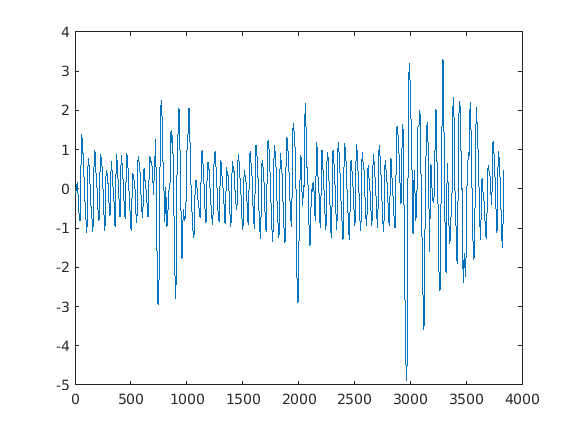

plot(PPG_ref_data_g)

%time=1:1:length(PPG_ref_data);
%time=time/fs_avg;
%for i=1:length(PPG_ref_data)
%    plot(time(i),PPG_ref_data(i),','MarkerFaceColor','b')
%    hold on
%    pause(.01)
%end

CI_Kur= createbound(X_train(:,1));

m = 1.8017

s = 0.4156

CI =     2.6328    0.9706


CI_Kur_=CI_Kur.*ones(length(X_train(:,1)),2);

CI_skew= createbound(X_train(:,2));

m = -0.1112

s = 0.3584

CI =     0.6056   -0.8281


CI_skew_=CI_skew.*ones(length(X_train(:,2)),2);


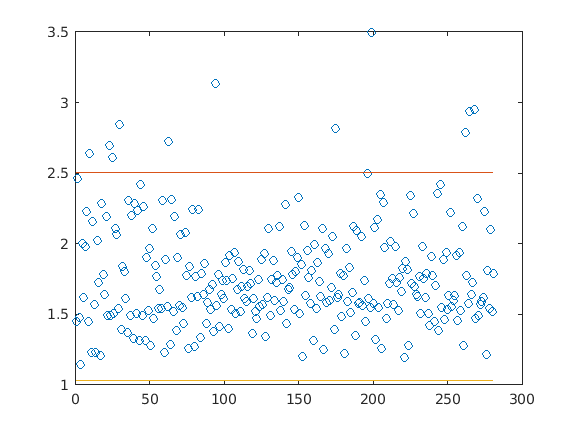

figure
plot(X_train(:,1),'o')
hold on
plot(CI_Kur_)

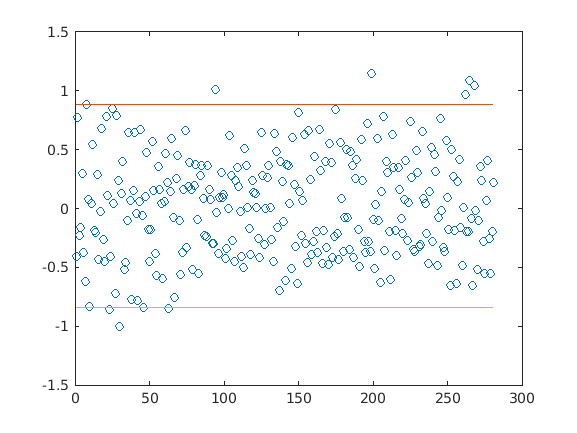


figure
plot(X_train(:,2),'o')
hold on
plot(CI_skew_)

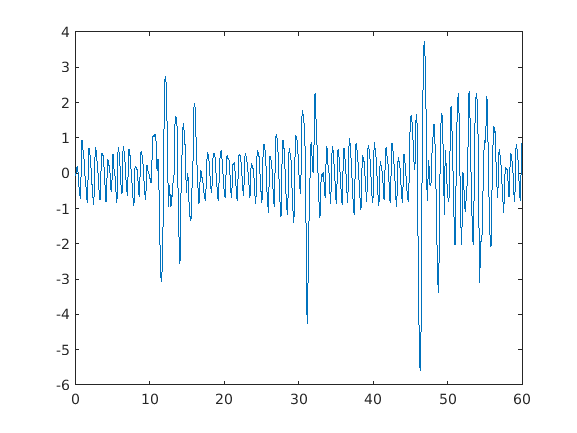

Test_data=readmatrix("testing.csv"); 
type='Maxem';


if strcmp(type,'Maxem')
    %Using Green LED signal
    PPG_data_g1=(Test_data(:,3));
    PPG_data_g2=(Test_data(:,4));
    PPG_data_r=(Test_data(:,5));
    PPG_data_ir=(Test_data(:,6));
    Data_accx=(Test_data(:,7));
    Data_accy=(Test_data(:,8));
    Data_accz=(Test_data(:,9));
    
    [perf_data_g1, PPG_data_g1] = pre_process(Butterworth,PPG_data_g1,fs_avg); 
    [perf_data, PPG_data_g2] = pre_process(Butterworth,PPG_data_g2,fs_avg); 
    [perf_data, PPG_data_r] = pre_process(Butterworth,PPG_data_r,fs_avg);
    [perf_data, PPG_data_ir] = pre_process(Butterworth,PPG_data_ir,fs_avg);%seperating perfusion and PPG waveform 
    
    [~, accx_data] = pre_process(Butterworth,Data_accx,fs_avg);
    [~, accy_data] = pre_process(Butterworth,Data_accy,fs_avg);
    [~, accz_data] = pre_process(Butterworth,Data_accz,fs_avg);

elseif strcmp(type,'Empatica')
    PPG_data=Test_data(15*fs_avg:length(Test_data)-1*fs_avg);
    [perf_data, PPG_data] = pre_process(Butterworth,PPG_data,fs_avg);
end

time=1:1:length(PPG_data_g1);
time=time/fs_avg;

%PPG_data=bandpass(PPG_data,[1 4],64)
figure
plot(time,PPG_data_g1)

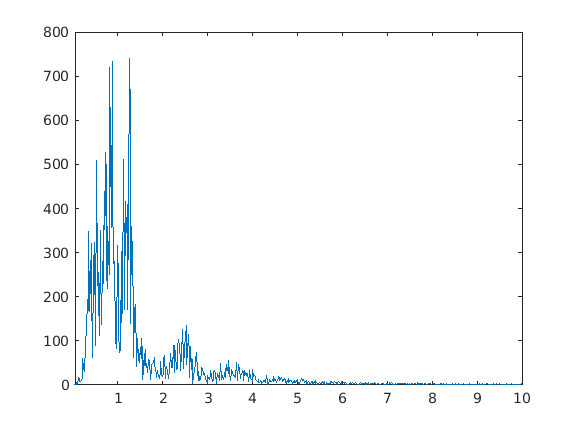

figure
freq_plot(PPG_data_g1,fs_avg)


PPG_data=[PPG_data_g1,transpose(time)];
ref_data=[PPG_data_g2,transpose(time)];
ref_accx=[Data_accx,transpose(time)];
ref_accy=[Data_accy,transpose(time)];
ref_accz=[Data_accz,transpose(time)];
ref_type = 1;
[X_test,~,~]=obtain_features(PPG_data(:,1),PPG_data(:,1),window,Overlap_perc,fs_avg,ref_type,perf_data_g1);


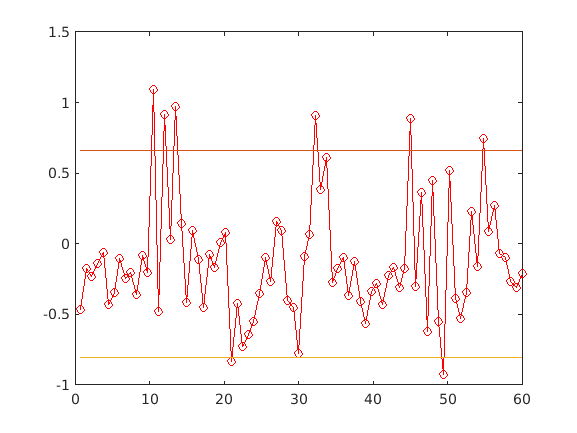

CI_skew_=CI_skew.*ones(length(X_test(:,3)),2);
figure
plot(X_test(:,3),X_test(:,2),'r-o')
hold on
plot(X_test(:,3),CI_skew_)

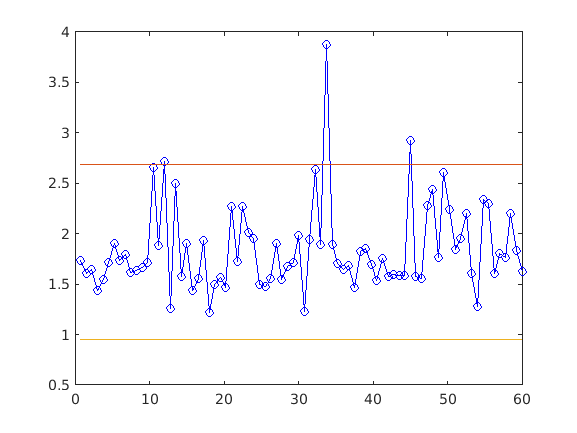


CI_kur_=CI_Kur.*ones(length(X_test(:,3)),2);
figure
plot(X_test(:,3),X_test(:,1),'b-o')
hold on
plot(X_test(:,3),CI_kur_)

dim =      2     2


total_windows = 2

    12



i = 1

ans = 129

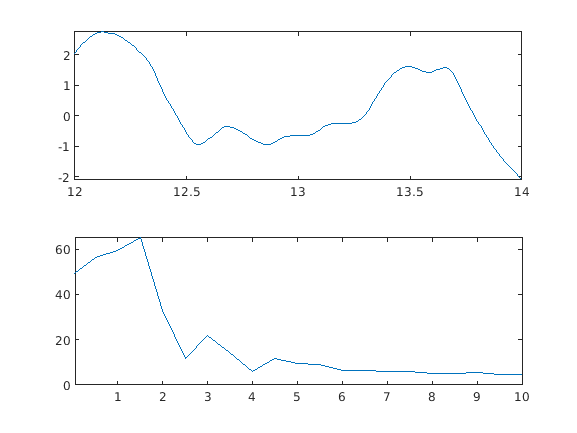

i = 2

ans = 129

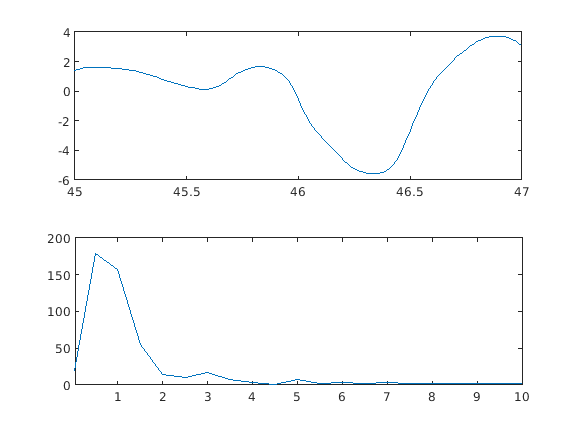


jump=2;
windows=get_windows(X_test,jump,CI_Kur,CI_skew);
[temp]=visualize(windows,PPG_data,ref_data);

% figure
% plot(PPG_data(:,1))
% figure
% plot(temp(:,1))

[~,~,PPG_data_proc] = obtain_features(PPG_data(:,1),ref_data(:,1),window,Overlap_perc,fs_avg,ref_type,perf_data_g1);
ref_type2 = 2;
[~,~,PPG_data_proc_accx] = obtain_features(PPG_data(:,1),ref_accx(:,1),window,Overlap_perc,fs_avg,ref_type2,perf_data_g1);
[~,~,PPG_data_proc_accy] = obtain_features(PPG_data(:,1),ref_accy(:,1),window,Overlap_perc,fs_avg,ref_type2,perf_data_g1);
[~,~,PPG_data_proc_accz] = obtain_features(PPG_data(:,1),ref_accz(:,1),window,Overlap_perc,fs_avg,ref_type2,perf_data_g1);

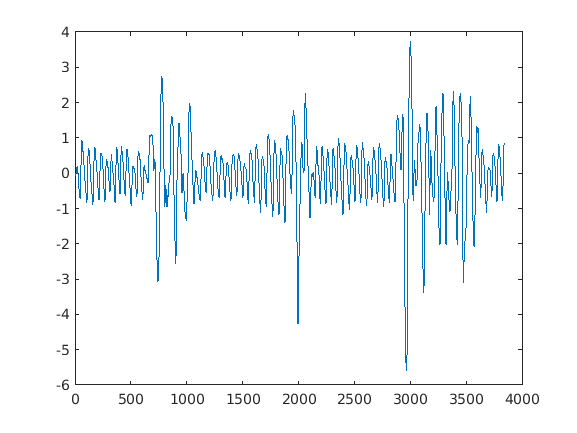

figure
plot(PPG_data(:,1))

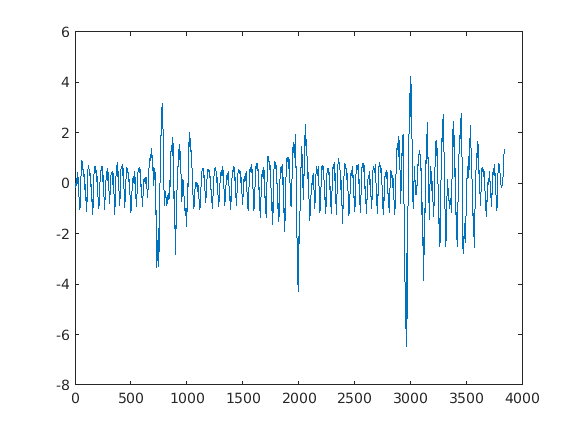

figure
plot(PPG_data_proc)

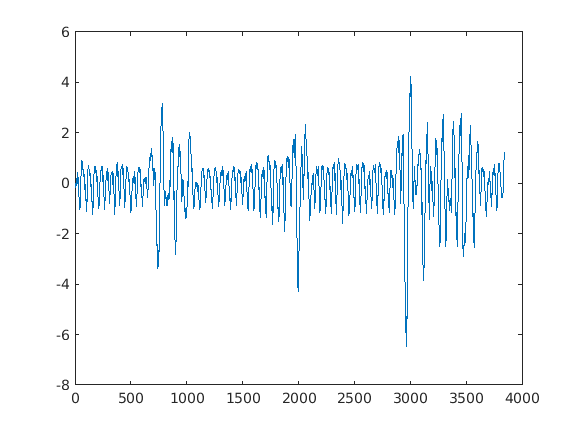

figure
plot(PPG_data_proc_accx)

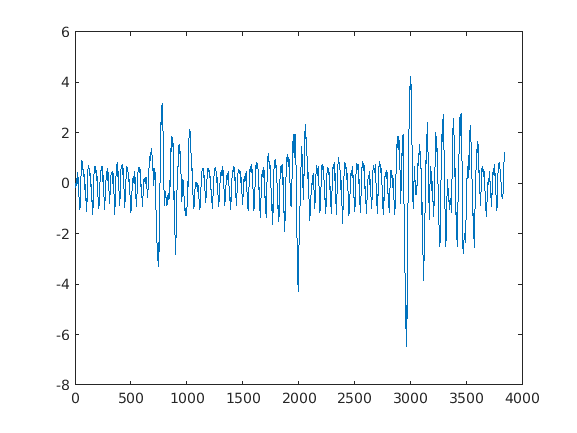

figure
plot(PPG_data_proc_accy)

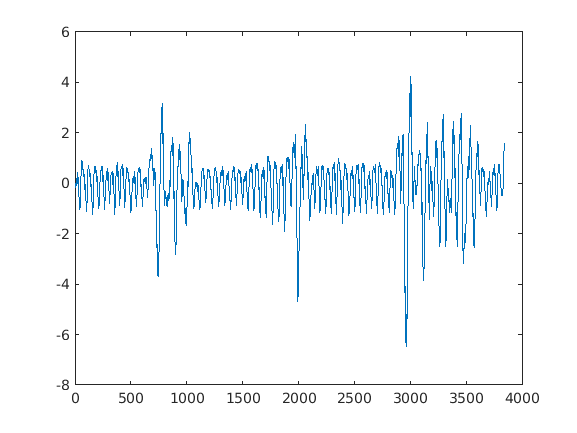


figure
plot(PPG_data_proc_accz)

%figure
%plot(temp(:,1))
%Snr_filtered=snr(temp(:,1))
%Snr_original=snr(PPG_data(:,1))

%Raw PPG
[feature_matrix_raw,t1,~] = obtain_features(PPG_data(:,1),PPG_data(:,1),window,Overlap_perc,fs_avg);
Kurtosis_SQI_raw = feature_matrix_raw(:,1);
Skewness_SQI_raw = feature_matrix_raw(:,2);
Perfusion_SQI_raw = feature_matrix_raw(:,4);
SNR_SQI_raw = feature_matrix_raw(:,5);
Zero_crossing_SQI_raw = zero_crossing(PPG_data(:,1));
%Z_raw = sum(Zero_crossing_SQI_raw);

%Processed PPG
[feature_matrix,t2,~] = obtain_features(PPG_data(:,1),transpose(PPG_data_proc),window,Overlap_perc,fs_avg);
Kurtosis_SQI = feature_matrix(:,1);
Skewness_SQI = feature_matrix(:,2);
Perfusion_SQI = feature_matrix(:,4);
SNR_SQI = feature_matrix(:,5);
Zero_crossing_SQI = zero_crossing(temp(:,1)); 
%Z = sum(Zero_crossing_SQI);

time = feature_matrix(:,3);

% Skewness
p_skew = ranksum(Skewness_SQI_raw,Skewness_SQI);

figure
plot(time,Skewness_SQI_raw,'r-o');
title('Skewness Raw');
hold on;
figure
plot(time,Skewness_SQI,'b-o');
title('Skewness Processed');
hold off;

% Zero-crossing
%p_zero_cross = ranksum(Zero_crossing_SQI_raw,Zero_crossing_SQI);

%Zero_crossing_SQI_raw
%Zero_crossing_SQI
% figure
% plot(time,Zero_crossing_SQI_raw,'r');
% hold on;
% figure
% plot(time,Zero_crossing_SQI,'b');
% hold off;

%Kurtosis
p_kurtosis = ranksum(Kurtosis_SQI_raw,Kurtosis_SQI);

figure
plot(time,Kurtosis_SQI_raw,'r-o');
title('Kurtosis Raw');
hold on;
figure
plot(time,Kurtosis_SQI,'b-o');
title('Kurtosis Processed');
hold off;

% Perfusion
p_perfusion = ranksum(Perfusion_SQI_raw,Perfusion_SQI);

figure
plot(time,Perfusion_SQI_raw,'r-o');
title('Perfusion Raw');
hold on;
figure
plot(time,Perfusion_SQI,'b-o');
title('Perfusion Processed');
hold off;

%SNR
p_SNR = ranksum(SNR_SQI_raw,SNR_SQI);

figure
plot(time,SNR_SQI_raw,'r-o');
title('SNR Raw');
hold on;
figure
plot(time,SNR_SQI,'b-o');
title('SNR Processed');
hold off;

p_skew
mean(Skewness_SQI_raw)
std(Skewness_SQI_raw)

mean(Skewness_SQI)
std(Skewness_SQI)

%p_zero_cross
p_perfusion
mean(Perfusion_SQI_raw)
std(Perfusion_SQI_raw)

mean(Perfusion_SQI)
std(Perfusion_SQI)

p_kurtosis
mean(Kurtosis_SQI_raw)
std(K_SQI_raw)

p_SNR

% raw
CI_Kur= createbound(feature_matrix_raw(:,1));
CI_Kur_raw=CI_Kur.*ones(length(feature_matrix_raw(:,1)),2);

CI_skew= createbound(feature_matrix_raw(:,2));
CI_skew_raw=CI_skew.*ones(length(feature_matrix_raw(:,2)),2);

% processed
CI_Kur2= createbound(feature_matrix(:,1));
CI_Kur_proc=CI_Kur2.*ones(length(feature_matrix(:,1)),2);

CI_skew2= createbound(feature_matrix(:,2));
CI_skew_proc=CI_skew2.*ones(length(feature_matrix(:,2)),2);


% raw
figure
plot(feature_matrix_raw(:,1),'r-o')
hold on
plot(CI_Kur_raw)

figure
plot(feature_matrix_raw(:,2),'r-o')
hold on
plot(CI_skew_raw)

%processed
figure
plot(feature_matrix(:,1),'b-o')
hold on
plot(CI_Kur_proc)

figure
plot(feature_matrix(:,2),'b-o')
hold on
plot(CI_skew_proc)
hold off


function [PPG_data]=visualize(windows,PPG_data,reference,ref_type)
    dim=size(windows)
    total_windows=dim(1)
    display(windows(1,1))
    for i=1:total_windows
        display(i)
        init=windows(i,1);
        fin=windows(i,2);
        window_data=PPG_data(init*64:fin*64,1);
        ref_window_data=reference(init*64:fin*64,1);
       
       % window_size=fin-init;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %Code To filter the window here
        %% SGolay Filter
        [PPG_sig,Ref_sig] = SGolay_Filter(window_data,ref_window_data,window);
        
        %% Adaptive Filter
        [PPG_Data] = AdaptiveFilter(PPG_sig,Ref_sig,ref_type);
   
        %% Notch Filter
        if prev_pos > fs*5
            [HRF] = HeartRate(PPG_Data(prev_pos-fs*5:prev_pos))
%               [PPG_sig_proc] = NotchFilter(PPG_Data,HRF);
        end
        
        PPG_data(init*64:fin*64,1)=ppg_IR;    
            
        %else
            %PPG_data(init*64:fin*64,1)=1;
        %end
        
        %d=window_data;
        %x=window_data-ref_data;
        %mu=0.05;
        %lms=dsp.LMSFilter(10000,'Method','Normalized LMS','StepSize',mu)
        %[y,error] = lms(x,d);
        
        
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        time=init*64:1:fin*64;
        time=time/64;
        figure
        subplot(2,1,1)
        plot(time,window_data)
        subplot(2,1,2)
        freq_plot(window_data,64)
        %figure
        %plot(SNR_total)
    end
end
function khirki = get_windows(X_test,jump,CI_Kur,CI_skew)

    window=[];
    time_init=0;
    time_final=0;
    windows=[];
    i=1;
    
    while i < length(X_test(:,1))
        if ((X_test(i,1)>CI_Kur(1)) ||  (X_test(i,1)<CI_Kur(2))) && ((X_test(i,2)>CI_skew(1)) ||  (X_test(i,2)<CI_skew(2)))
            time_init=round(X_test(i,3)-0.5);
            if time_init==0
                time_init=1;
            end
            window=[];
            prev_time=time_init;
            time_final=0;
            index=i;
            
            while 1
                count_motion=0;
                if prev_time + jump > length(X_test(:,1))
                    break
                end
                while X_test(index,3) < prev_time + jump
                    if ((X_test(index,1)>CI_Kur(1)) ||  (X_test(index,1)<CI_Kur(2))) && ((X_test(index,2)>CI_skew(1)) ||  (X_test(index,2)<CI_skew(2)))
                        count_motion=count_motion+1; 
                    end
                    index=index+1;
                    if index > length(X_test(:,1))
                        index=length(X_test(:,1));
                        break
                    end
                end
                if count_motion<1
                    break
                else
                    
                end
                prev_time=round(X_test(index,3));              
            end
            time_final=prev_time;
            if index> length(X_test(:,1))
                window=[time_init length(X_test(:,1))];
                break
            else
                window=[time_init time_final];
            end
            windows=[windows;window];
            i=index;
        end
        i=i+1;
    end
    khirki=windows;
end

function freq_plot(data,fs)
    FM = (abs(fftshift(fft(data)))); 	
    FF = linspace(-fs/2,fs/2,length(FM)); 
    plot(FF,FM)
    xlim([0.05 10])
end


function [perf, PPG] = pre_process(fil,data,fs)
    perf=sgolayfilt(data,2,4*fs +1);
    PPG=data-perf;
    PPG=-1*PPG;
    PPG=filter(fil,PPG);
    PPG=normalize(PPG);
    
end

function CI= createbound(data)
    m=mean(data)
    s=std(data)
    CI=[m+2*s m-2*s]
    %CI=CI.*ones(length(X_train(:,1)),2)
end

function [feature_matrix,time,PPG_data]=obtain_features(raw_data,data,window_size,Overlap,fs,ref_type,Perf_sig)
    Input_data=data;
    Input_raw =raw_data;
    window=window_size;
    Overlap_perc=Overlap;
    
    current_pos=1;
    prev_pos=1;
    last_iter=0;
    
    Kur=[];
    Skew=[];
    P_SQI=[];
    %Z_SQI=[];
    SNR_SQI=[];
    Standard_dev=[];
    time=[];
    PPG_data=[];
    
    len_signal=length(Input_data);
    
    while 1
        if (prev_pos+window) < len_signal
            current_pos=prev_pos+window;
        else
            current_pos=len_signal;
            last_iter=1;
        end
        
        data_segment=Input_data(prev_pos:current_pos);
        data_segment_raw=Input_raw(prev_pos:current_pos);
        perf_data=Perf_sig(prev_pos:current_pos);
        Kur=[Kur kurtosis(data_segment)];
        Skew=[Skew skewness(data_segment)];
        P_SQI=[P_SQI perfusion_SQI(data_segment_raw,data_segment)];
        SNR_SQI=[SNR_SQI SNR(data_segment)];
        %Z_SQI=[Z_SQI zero_crossing(data_segment)];
        Standard_dev=[Standard_dev std(data_segment)];
        
        %% SGolay Filter
        [PPG_sig,Ref_sig] = SGolay_Filter(data_segment_raw,data_segment,window);
        
        %% Adaptive Filter
        [PPG_Data] = AdaptiveFilter(PPG_sig,Ref_sig,ref_type);
   
        %% Notch Filter
        if prev_pos > fs*5
            [HRF] = HeartRate(raw_data(prev_pos-fs*5:prev_pos));
            [PPG_sig_proc] = NotchFilter(PPG_Data,HRF,fs);
        else
            PPG_sig_proc = PPG_Data;
        end
        PPG_data(prev_pos:current_pos) = PPG_sig_proc;
        
        if last_iter==0
            time=[time current_pos/fs];
        elseif last_iter==1
            time=[time len_signal/fs];
            break
        end
        
        prev_pos=current_pos- round((Overlap_perc/100) *window);
    end
    
    Kur=transpose(Kur);
    Skew=transpose(Skew);
    P_SQI=transpose(P_SQI);
    SNR_SQI=transpose(SNR_SQI);
    %Z_SQI=transpose(Z_SQI);
    Standard_dev=transpose(Standard_dev);
    time=transpose(time);
    %PPG_data=transpose(PPG_data);
    
    
    feature_matrix=[Kur,Skew,time,P_SQI,SNR_SQI];

end


function Hd = b_filter
%BUTTERWORTH Returns a discrete-time filter object.

% MATLAB Code
% Generated by MATLAB(R) 9.9 and Signal Processing Toolbox 8.5.
% Generated on: 03-Mar-2021 12:11:19

% Butterworth Bandpass filter designed using FDESIGN.BANDPASS.

% All frequency values are in Hz.
Fs = 64;  % Sampling Frequency

N   = 2;    % Order
Fc1 = 0.6;  % First Cutoff Frequency
Fc2 = 4;    % Second Cutoff Frequency

% Construct an FDESIGN object and call its BUTTER method.
h  = fdesign.bandpass('N,F3dB1,F3dB2', N, Fc1, Fc2, Fs);
Hd = design(h, 'butter');
end

function [Ta] = fundamental_period_extraction(x1)
    x = xcorr(x1);
    l = length(x);
    t_max = floor(l/3);
    t = 1:t_max;
    y = zeros(l,1);
    z = [];
    for i = 1:t_max
        y(i) = 1;
        y(2*i) = 0.9;
        y(3*i) = 0.8;
        z1 = y.*x;
        Z = fft(z1);
        pow = Z.*conj(Z);
        pow_acc = sum(Z);
        z = [z pow_acc];
    end
    [~,ind] = max(z);
    Ta = ind;
end
function [new_ref_sig1,new_ref_sig2] = B_optim(x1,x2,ref_sig,Ta,mu)
    %B_OPTIM Summary of this function goes here
    %   Detailed explanation goes here
    %lms = dsp.LMSFilter(640,'Method','mmse','StepSize',mu)
    %[ppg_red,error] = lms(new_ref_sig2,x1);
    
    rv = mean(x2./ref_sig);
    s_as = x1 - rv*x2;%dot(rv,transpose(x2));
    
    lms = dsp.LMSFilter('Length',64,'Method','LMS','StepSize',mu);
    [est_Sas] = lms(x1,s_as);
%    [mse,meanw,w,tracek] = msesim(lms,s_as,x1);
 %   est_Sas = filter([0 -w(2:end)],1,x2);
    est_Sas2 = x1 - est_Sas;
    filter_coeff = lpc(est_Sas2,Ta);
    
    a = (mean(x1.*x1,'all')-rv*mean(x1.*x2,'all'))/mean(s_as,'all');
    b = (a*rv)/(1-a);
%     if b > 20
%         b = 0.1;
%     end
    x3 =[];
    for i=1:length(x2)
        if x2(i)>x1(i)
            x3(i) = 0.95*x2(i);
        elseif x2(i)<x1(i)
            x3(i) = 1.05*x2(i);
        else
            x3(i) = x2(i);
        end
    end
        b = 1.05;
    %e1 = x1 - a.*s_as;
    
    
    new_ref_sig1 =  est_Sas2;
    new_ref_sig2 = x1 - x3'; 
    
end

function [Z_SQI] = zero_crossing(PPG)
    zcd = dsp.ZeroCrossingDetector;
    Z_SQI = zcd(PPG)/length(PPG);
end

function [P_SQI] = perfusion_SQI(raw_PPG,proc_PPG)
    P_SQI = 100*(max(proc_PPG)-min(proc_PPG))/abs(mean(raw_PPG));
end

function [SNR] = SNR(PPG)
    SNR = power(std(abs(PPG)),2)/power(std(PPG),2);
end

function [PPG_Data] = AdaptiveFilter(PPG_sig,Ref_sig,ref_type)
    d1 = PPG_sig;
    d2 = Ref_sig;
    if ref_type == 1
        ref = d1-d2;
        
        mu = 0.01;
        rls1 = dsp.RLSFilter(32,'Method','Sliding-window RLS','ForgettingFactor',0.999,'InitialInverseCovariance',0.1);
        [x1,~] = rls1(d1,ref);
        [x2,~] = rls1(d2,ref);
    
        [Ta] = fundamental_period_extraction(x1);
        [new_ref_sig1,new_ref_sig2] = B_optim(x1,x2,ref,Ta,mu);
        %lms = dsp.LMSFilter(32,'Method','Normalized LMS','StepSize',mu);
        rls2 = dsp.RLSFilter(32,'Method','Sliding-window RLS','ForgettingFactor',0.999,'InitialInverseCovariance',0.1);
        [ppg_red,~] = rls2(new_ref_sig2,x1);
        %[ppg_IR,~] = rls2(new_ref_sig2,x2);
    else
        ref = d2;

        rls1 = dsp.RLSFilter(32,'Method','Sliding-window RLS','ForgettingFactor',0.999,'InitialInverseCovariance',0.1);
        [x1,~] = rls1(d1,ref);
        [x2,~] = rls1(d2,ref);
        rls2 = dsp.RLSFilter(32,'Method','Sliding-window RLS','ForgettingFactor',0.999,'InitialInverseCovariance',0.1);
        [ppg_red,~] = rls2(d1-x1,x1);
    end


    PPG_Data = d1 - ppg_red; %(ppg_IR/max(ppg_IR));
end

function [PPG,Ref] = SGolay_Filter(PPG_sig,Ref_sig,wind_len)
    PPG = sgolayfilt(PPG_sig,3,wind_len-3);
    Ref = sgolayfilt(Ref_sig,3,wind_len-3);
end

function [HRF] = HeartRate(PPG_sig)
    [~,loc] = findpeaks(PPG_sig,64,'MinPeakDistance',0.7);
    peak_diff = [];
    for i=1:length(loc)-1
        peak_diff(i) = loc(i+1) - loc(i); 
    end
    HRF = mean(peak_diff);
end

function [PPG_sig_proc] = NotchFilter(PPG_sig,HRF,fs)
    
%     notchspec = fdesign.notch('N,F0,BW',6,HRF,0.1,fs);
%     notchfilt = design(notchspec,'SystemObject',true);
%     %fvt= fvtool(notchfilt, 'Color','white');
%     notchspec1 = fdesign.notch('N,F0,BW',6,2*HRF,0.1,fs);
%     notchfilt1 = design(notchspec1,'SystemObject',true);
    w0 = HRF/(fs/2);
    bw = w0/40;
    [b,a] = iirnotch(w0,bw);
    
    w1 = (HRF*2)/(fs/2);
    bw1 = w1/40;
    [b1,a1] = iirnotch(w1,bw1);
    
    proc_sig = filter(b,a,PPG_sig);
    proc_sig1 = filter(b1,a1,PPG_sig);
    
    noise = PPG_sig - proc_sig - proc_sig1;
    PPG_sig_proc = PPG_sig - noise;
    PPG_sig_proc = normalize(PPG_sig_proc);
end

function [PPG_sig_proc] = PeakFilter(PPG_sig,HRF)
    
    peakspec = fdesign.peak('N,F0,BW',3,HRF,0.1);
    peakfilt = design(peakspec,'SystemObject',true);
    %fvt= fvtool(notchfilt, 'Color','white');
    
    PPG_sig_proc = filter(peakfilt,PPG_sig);
end
